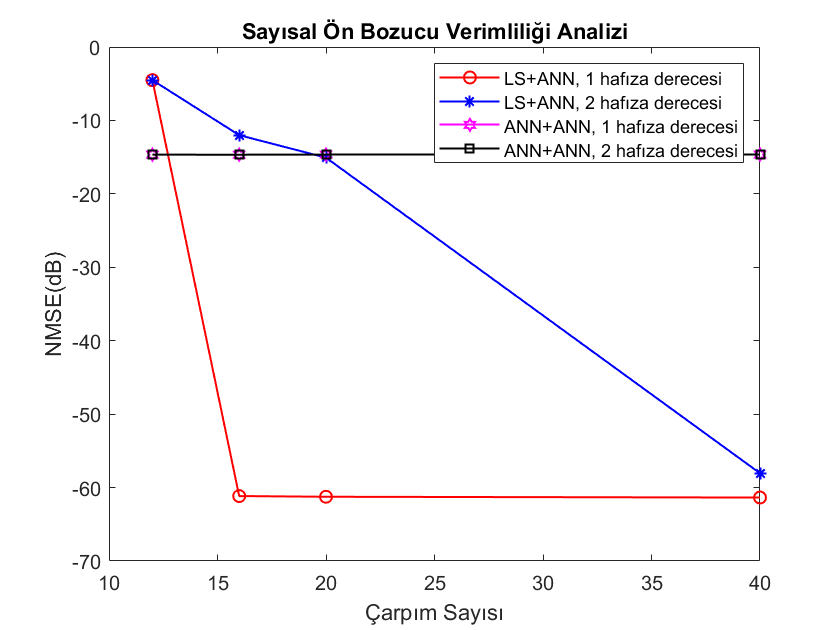

comp = [12, 16, 20, 40];%,, 45 140];
evm_LS_ANN_0mem = [4.1456e-04, 4.0431e-04, 4.0793e-04];%, 4.0392e-04];
evm_LS_ANN_1mem = [0.3572, 8.7538e-04, 8.6583e-04, 8.5526e-04];%,, 8.6999e-048.6756e-04];
evm_LS_ANN_2mem = [0.5951, 0.2510, 0.1764, 0.0013];%,, 0.0012 0.0012];
evm_ANN_ANN_0mem = [0.1852, 0.1852, 0.1848, 0.1846];
evm_ANN_ANN_1mem = [0.1848, 0.1848, 0.1852, 0.1852];%,, 0.1848 0.1846];
evm_ANN_ANN_2mem = [0.1848, 0.1848, 0.1852, 0.1852];%,, 0.1855 0.1846];

% nmse_LS_ANN_0mem = [1HL3N, 1HL4N, 1HL5N, 1HL10N, 2HL5N, 2HL10N];
nmse_LS_ANN_1mem = [-4.5085, -61.1561, -61.2514, -61.3580];%,, -61.2097, -61.2340];
nmse_LS_ANN_2mem = [-4.5085, -12.0066, -15.0700, -58.0472];%,, -15.1344, -58.0675];
% nmse_ANN_ANN_0mem = [1HL3N, 1HL4N, 1HL5N, 1HL10N, 2HL5N, 2HL10N];
nmse_ANN_ANN_1mem = [-14.6640, -14.6673, -14.6484, -14.6462];%,, -14.6648, -14.6739];
nmse_ANN_ANN_2mem = [-14.6640, -14.6673, -14.6484, -14.6462];%,, -14.6648, -14.6739];

%% Plot AM-AM after predistortion
figure; %subplot(2,1,1);
plot( comp, nmse_LS_ANN_1mem, '-or', 'LineWidth',1);
hold on;
plot(comp, nmse_LS_ANN_2mem,  '-*b', 'LineWidth', 1); 
hold on;
plot(comp, nmse_ANN_ANN_1mem, '-hm', 'LineWidth', 1);
hold on;
plot(comp, nmse_ANN_ANN_2mem, '-sk', 'LineWidth', 1); 

xlabel('Çarpım Sayısı'); 
ylabel('NMSE(dB)');%'EVM (%)'
legend('LS+ANN, 1 hafıza derecesi', 'LS+ANN, 2 hafıza derecesi', 'ANN+ANN, 1 hafıza derecesi', 'ANN+ANN, 2 hafıza derecesi');
title('Sayısal Ön Bozucu Verimliliği Analizi');
% axis([min(abs()) max(abs(Z_n)) 0 1]); 
hold off;